Textfile = load("capture.txt")

Textfile =    89.4460
   26.1035
   35.7470
   34.7221
   49.2431
   55.4208
   89.1215
   20.6131
   37.0284
   98.7423


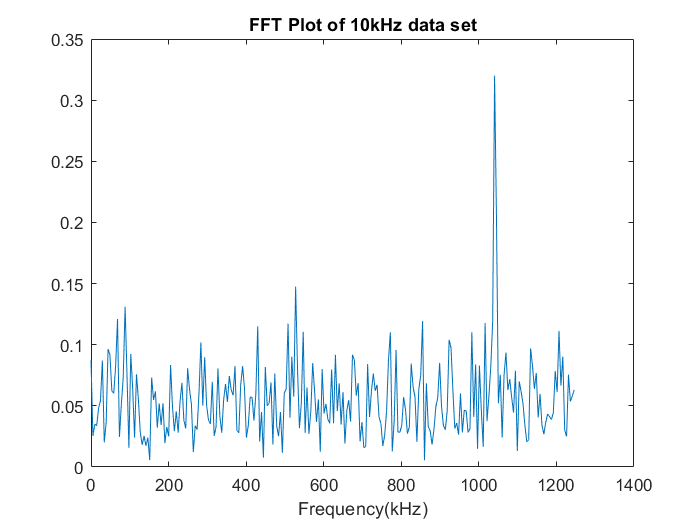

writematrix(Textfile, "capture.csv");
FFTData = readtable("capture.csv");


N = 2048 - 1; 
FFTData = FFTData{:, 1}/N *2; %data is symmetric, *2 to account for contribution of other half 
fs = 10000;
frequency = fs*(0:(N/2))/N;

plot(frequency(1:256), FFTData(1:256)); %only plotting the real side of the dataset 
title("FFT Plot of 10kHz data set");
xlabel("Frequency(kHz)");